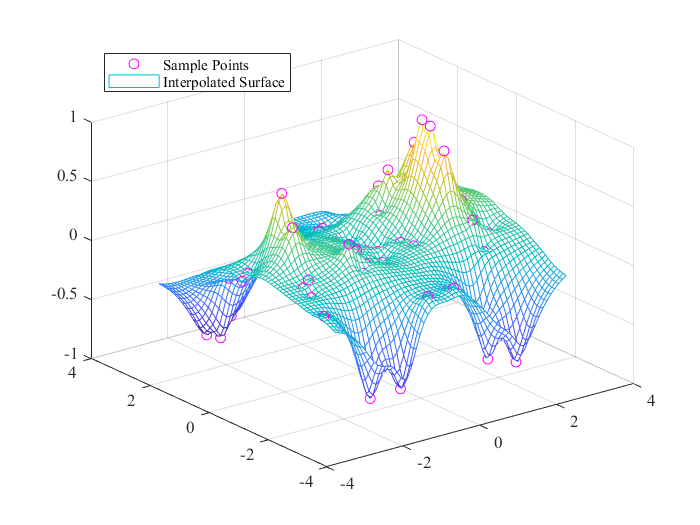

% 创建包含 50 个散点的样本数据集。这里有意使用较少的点数量，目的是为了突出插值方法之间的差异。
clear all
close all
rng(10) % 使用种子10初始化随机数生成器
X = -3 + 6*rand(50,1);
Y = -3 + 6*rand(50,1);
V = sin(X).^4 .* cos(Y);
% 创建一个查询点网格。

[xq,yq] = meshgrid(-3:0.1:3);
% 使用 'nearest'、'linear'、'natural' 和 'cubic' 方法插入样本数据。绘制结果进行比较。
%vq = sin(xq).^4 .* cos(yq)
%vq = IDW(X,Y,V,xq,yq,numel(X))
vq = IDW(X,Y,V,xq,yq,32);
plot3(X,Y,V,'mo')
hold on
mesh(xq,yq,vq)
%title('IDW Interpolation')
legend('Sample Points','Interpolated Surface','Location','NorthWest')
set(gca, 'FontName','Times New Roman');
grid on

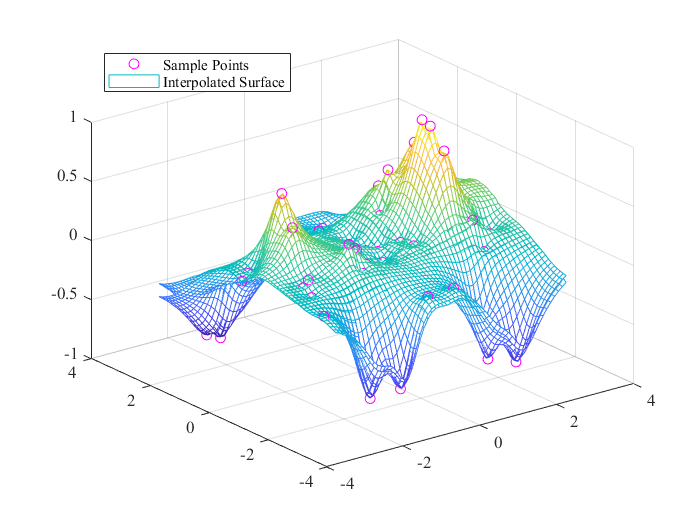

vq = IDW(X,Y,V,xq,yq,16);
plot3(X,Y,V,'mo')
hold on
mesh(xq,yq,vq)
%title('IDW Interpolation')
legend('Sample Points','Interpolated Surface','Location','NorthWest')
set(gca, 'FontName','Times New Roman');
grid on

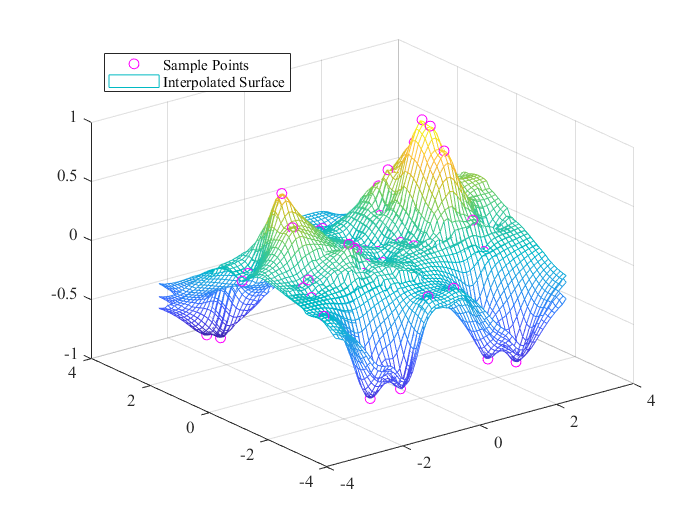

vq = IDW(X,Y,V,xq,yq,8);
plot3(X,Y,V,'mo')
hold on
mesh(xq,yq,vq)
%title('IDW Interpolation')
legend('Sample Points','Interpolated Surface','Location','NorthWest')
set(gca, 'FontName','Times New Roman');
grid on

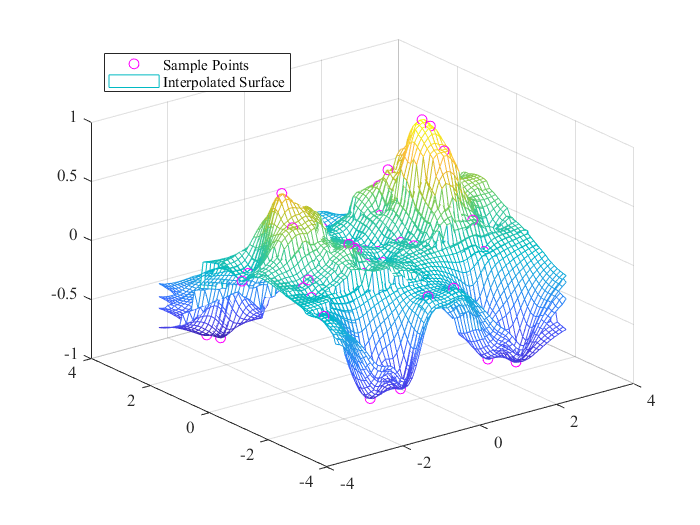

vq = IDW(X,Y,V,xq,yq,4);
plot3(X,Y,V,'mo')
hold on
mesh(xq,yq,vq)
%title('IDW Interpolation')
legend('Sample Points','Interpolated Surface','Location','NorthWest')
set(gca, 'FontName','Times New Roman');
grid on

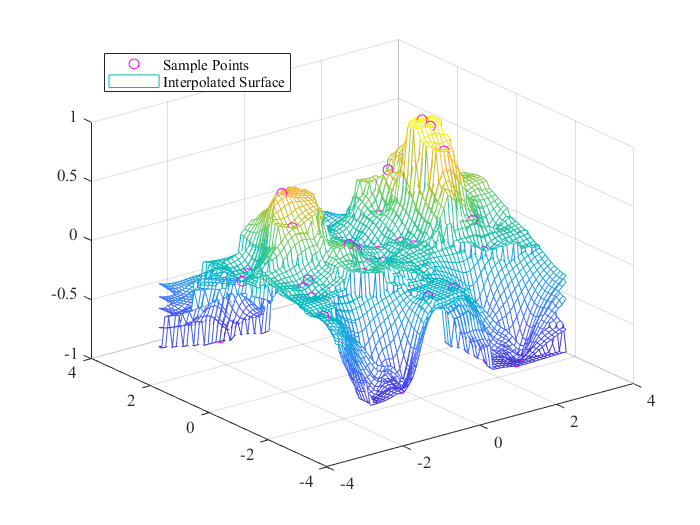

vq = IDW(X,Y,V,xq,yq,2);
plot3(X,Y,V,'mo')
hold on
mesh(xq,yq,vq)
%title('IDW Interpolation')
legend('Sample Points','Interpolated Surface','Location','NorthWest')
set(gca, 'FontName','Times New Roman');

grid on